## 1－3 和4－9,10－16和 17－23

## 不同地区做差异

## 1－3 和10－16,4－9 和17－23

## 同地区不同品类做关联

clc;clear;close all;
data=readmatrix("数据.xlsx")

data =     0.0754    0.0042    0.0463    0.2005    0.0364
    0.0398    0.1090    0.0182    0.0359    0.0110
    0.0353    0.1399    0.0352    0.1026    0.0131
    0.1184    0.0175    0.0409    0.2975    0.0135
    0.0609    0.1011    0.0456    0.1475    0.0113
    0.0739    0.0036    0.0262    0.0331    0.0181
    0.0517    0.0381    0.0403    0.2627    0.0193
    0.0376    0.0161    0.0218    0.0390    0.0140
    0.0574    0.0017    0.0235    0.1003    0.1518
    0.0366    0.0072    0.0075    0.0198    0.0444


zm=data(1:3,:);
cym=data(4:9,:);
zg=data(10:16,:);
cyg=data(17:23,:);

## 主成分分析

选取各个区域的中贡献度最高的主成分

[~,zm_ind]=pca(zm');zm_=zm(zm_ind(1),:);
[~,cym_ind]=pca(cym');cym_=cym(cym_ind(1),:);
[~,zg_ind]=pca(zg');zg_=zg(zg_ind(1),:);
[~,cyg_ind]=pca(cyg');cyg_=cyg(cyg_ind(1),:);

## 差异性分析

1－3 和4－9不同地区做差异（zm_与cym_）

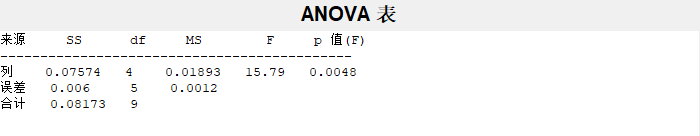

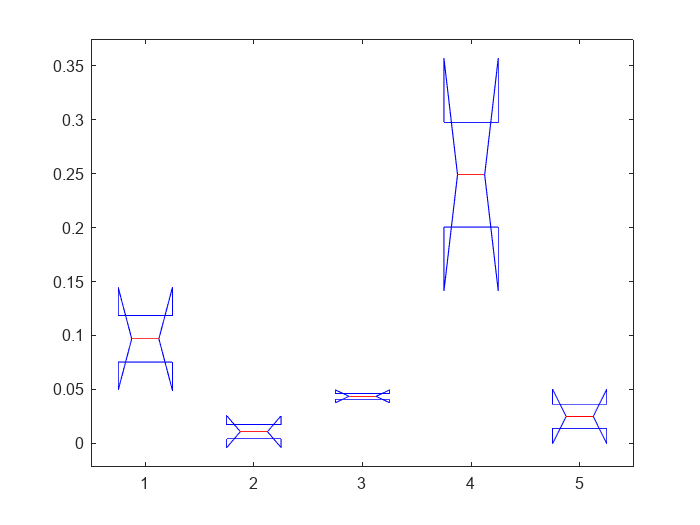

X=[zm_;cym_];
[p,table,stats]=anova1(X);

**返回值0.0048<0.05，认为zm与cym地区所测得的重金属含量有显著差异**

**从方差分析box图容易看出zm与cym地区所测得的重金属含量之间的直观差异**

## 10－16和 17－23

## 不同地区做差异（zg与cyg）

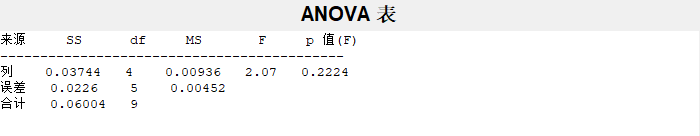

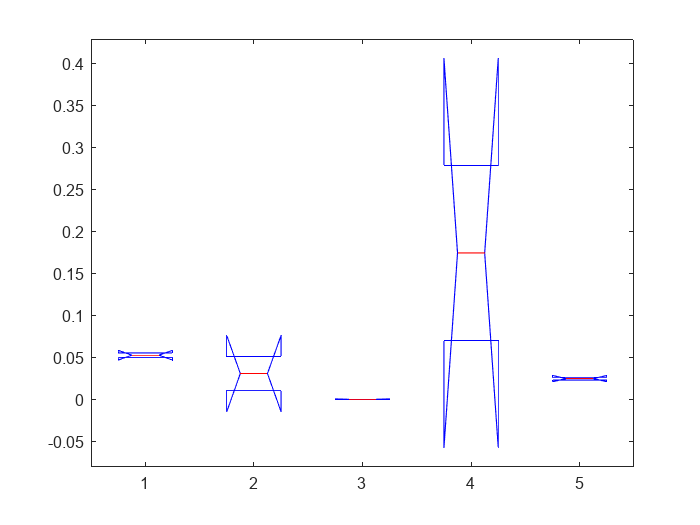

X=[zg_;cyg_];
[p,table,stats]=anova1(X);

**返回值0.2224<0.05，认为zg与cyg地区所测得的重金属含量无显著差异**

## 1－3 和10－16,4－9 和17－23

## 同地区不同品类做关联

## 1－3 和10－16同地区不同品类做关联(zm与zg)

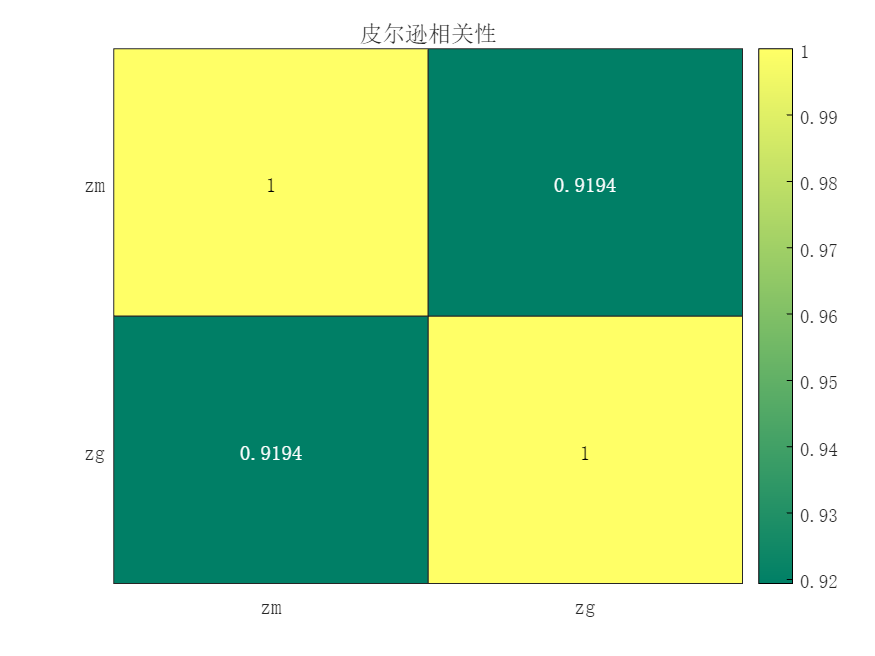

data=[zm_' zg_'];
figure
% 求维度之间的相关系数
rho = corr(data, 'type','pearson');
% 绘制热图
string_name={'zm','zg'};
xvalues = string_name;
yvalues = string_name;
h = heatmap(xvalues,yvalues, rho, 'FontSize',10, 'FontName','宋体');
h.Title = '皮尔逊相关性';
colormap summer

## 很明显，zm与zg的正相关性很强，可以说明同地区不同种类关联性较大

## 4－9 和17－23

## 同地区不同品类做关联（cym，cyg）

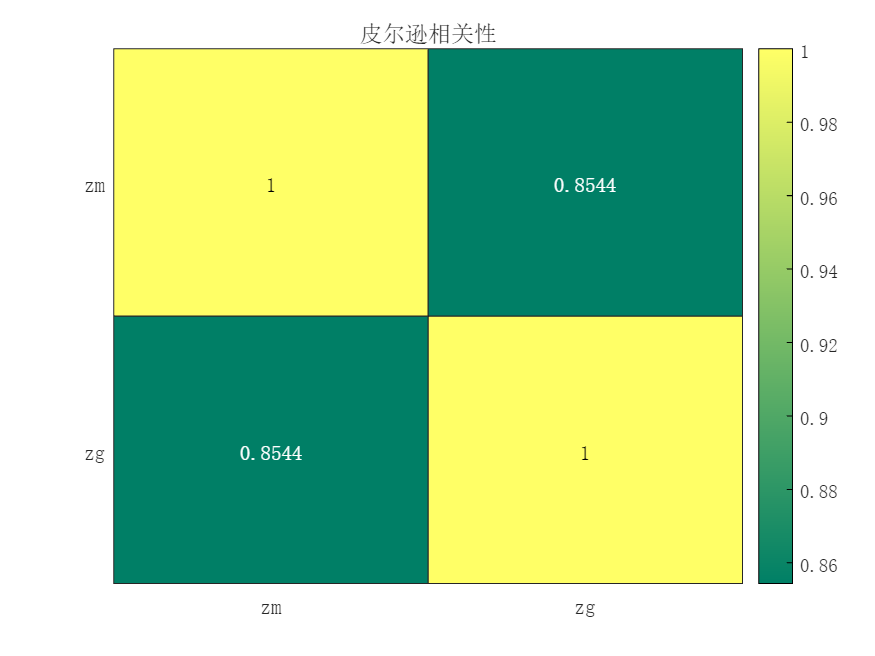

data=[cym_' cyg_'];
figure
% 求维度之间的相关系数
rho = corr(data, 'type','pearson');
% 绘制热图
string_name={'zm','zg'};
xvalues = string_name;
yvalues = string_name;
h = heatmap(xvalues,yvalues, rho, 'FontSize',10, 'FontName','宋体');
h.Title = '皮尔逊相关性';
colormap summer

## 同样，cym与cyg的正相关性很强，也可以说明同地区不同种类关联性较大

function [stf,ind]=pca(data)
    data=zscore(data');     %数据的标准化
    r=corrcoef(data);      %计算相关系数矩阵r
    %下面利用相关系数矩阵进行主成分分析，vec1的第一列为r的第一特征向量，即主成分的系数
    [vec1,lamda,rate]=pcacov(r);                 %lamda为r的特征值，rate为各个主成分的贡献率
    f=repmat(sign(sum(vec1)),size(vec1,1),1);    %构造与vec1同维数的元素为±1的矩阵
    vec2=vec1.*f;             %修改特征向量的正负号，使得每个特征向量的分量和为正，即为最终的特征向量
    num = max(find(lamda>1)); %num为选取的主成分的个数,这里选取特征值大于1的
    df=data*vec2(:,1:num);    %计算各个主成分的得分
    tf=df*rate(1:num)/100;    %计算综合得分
    [stf,ind]=sort(tf,'descend');  %把得分按照从高到低的次序排列
    stf=stf'; ind=ind';            %stf为得分从高到低排序，ind为对应的样本编号
end